% Método de mínimos cuadrados
% Desarrollado por:
% 
% Federico Banoy restrepo
% Juan David Rengifo
% Salomón Cardeño Luján


% Parámetros del modelo ARX(na,nb,nk)
na = 1;
nb = 2;
nk = 1;
d = nk-1;% nk CM (retardo d = nk-1)
canta = true; % ¿Corregir singularidad?

% Datos [t, u, y]
t = 0:7; % Tiempo
n = length(t); % Número de observaciones
u = ones(1, n); % Entrada
y = [0.0090, 1.1278, 1.2867, 1.3367, 1.3554, 1.3625, 1.3662, 1.3635]; % Salida
datos = [t; u; y]' % Visualizar datos

datos =          0    1.0000    0.0090
    1.0000    1.0000    1.1278
    2.0000    1.0000    1.2867
    3.0000    1.0000    1.3367
    4.0000    1.0000    1.3554
    5.0000    1.0000    1.3625
    6.0000    1.0000    1.3662
    7.0000    1.0000    1.3635



% Mínimo necesito Q = max(na, nd+d) datos
Q = max(na, nb+d);
if n > Q
    % Corrige problemas de singularidad añadiendo más datos a la entrada al
    % agregar ceros para para el pasado.
    if canta
        aux = pexcit(iddata(y',u',1)); % ¿Cuántos ceros se ponen?
        u = [zeros(1, aux), u];
        Q = Q - aux;
    end
    
    % Número de datos empleados para la estimación.
    N = n - Q;
    % Prealocación.
    PHI = zeros(N, na+nb);
    % Recorto los primeros Q datos de la salida.
    Y = y((Q+1):end)';
    
    % Llenar la matriz PHI siguiendo el orden de las notas de clase de
    % Daniel.
    for i = 1:length(PHI)
        if canta % Caso en el que se corrige la singularidad
            PHI(i,:) = [-y((i+d+na-1):-1:(i+d)), u((i+nb-1):-1:i)];
        else % Caso en el que no se corrige
            PHI(i,:) = [-y((i+d+na):-1:(i+d+1)), u((i+nb-1):-1:i)];
        end
    end
    PHI
    % Estimación de parámetros
    theta = (PHI'*PHI)\PHI'*Y
    % Ecuación del ARX_{na, nb, nk} estimada
    modelo = str2sym(eq_arx(theta, na, nb, nk))

Sabemos que un modelo ARX($\textrm{na},\textrm{nb},\textrm{nk}$) es de la forma


$$\begin{array}{l}
A\left(q\right)y\left(t\right)=B\left(q\right)u\left(t\right)+e\left(t\right)\\
A\left(q\right)=1+a_1 q^{-1} +a_2 q^{-2} +\ldotp \ldotp \ldotp +a_{na} q^{-na} ,\;B\left(q\right)=\left(b_1 q^{-1} +b_2 q^{-2} +\ldotp \ldotp \ldotp +b_{nb} q^{-nb} \right)q^{-nk} ,nk\ge 0
\end{array}$$


Entonces la función de transferencia de un modelo ARX($na,nb,nk$) asumiendo que el error $e\left(t\right)=0$ es


$$G=\frac{Y}{U}=\frac{B\left(q\right)}{A\left(q\right)}=\frac{\left(b_1 q^{-1} +b_2 q^{-2} +\ldotp \ldotp \ldotp +b_{nb} q^{-nb} \right)q^{-nk} }{1+a_1 q^{-1} +a_2 q^{-2} +\ldotp \ldotp \ldotp +a_{na} q^{-na} }$$
 

En este caso se tiene un ARX($1,2,1$) entonces su función de transferencia es


$$G=\frac{\left(b_1 q^{-1} +b_2 q^{-2} \right)q^{-1} }{1+a_1 q^{-1} }=\frac{\left(1\ldotp 1248q^{-1} -0\ldotp 21296q^{-2} \right)q^{-1} }{1-0\ldotp 33181q^{-1} }$$


    % Salida estimada
    y_est = PHI*theta;
    % Residuales
    res = Y - y_est;
    
    % Verificar que la media es cero, pues es un supuesto
    media = mean(res)
    
    % Varianza
    % lambda2 = sum(res.^2 - mean(res)) / (N - (na+nb));
    lambda2 = sum(res.^2) / (N - (na+nb))
    covarianza = lambda2*inv(PHI'*PHI)
    
    % Desviación estándar de los parámetros
    sd = sqrt(diag(covarianza))
    ci = [theta-sd, theta+sd]
    
    

Los intervalos de confianza de los parámetros son de la forma $\hat{\theta} \pm \mathrm{sd}$, donde $\hat{\;\theta \;}$ es el vector de parámetros estimados y $\mathrm{sd}$ es su respectiva desviación estándar. En este caso se tiene:


$$\hat{\theta} \pm \mathrm{sd}=\left\lbrack \begin{array}{c}
a_1 \\
b_1 \\
b_2 
\end{array}\right\rbrack \pm \left\lbrack \begin{array}{c}
{\mathrm{sd}}_{a_1 } \\
{\mathrm{sd}}_{b_1 } \\
{\mathrm{sd}}_{b_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-0\ldotp 3318\\
1\ldotp 1248\\
-0\ldotp 2130
\end{array}\right\rbrack \pm \left\lbrack \begin{array}{c}
0\ldotp 0089\\
0\ldotp 0018\\
0\ldotp 0117
\end{array}\right\rbrack$$


PHI =    -0.0090    1.0000         0
   -1.1278    1.0000    1.0000
   -1.2867    1.0000    1.0000
   -1.3367    1.0000    1.0000
   -1.3554    1.0000    1.0000
   -1.3625    1.0000    1.0000
   -1.3662    1.0000    1.0000


theta =    -0.3318
    1.1248
   -0.2130


$$modelo = y\left(t\right)-0.33181\,y\left(t-1\right)=1.1248\,u\left(t-2\right)-0.21296\,u\left(t-3\right)$$

media = -2.5377e-16

lambda2 = 3.3736e-06

covarianza = 	1.0e+-3 *

    0.0797    0.0007    0.1034
    0.0007    0.0034   -0.0024
    0.1034   -0.0024    0.1380


sd =     0.0089
    0.0018
    0.0117


ci =    -0.3407   -0.3229
    1.1230    1.1267
   -0.2247   -0.2012


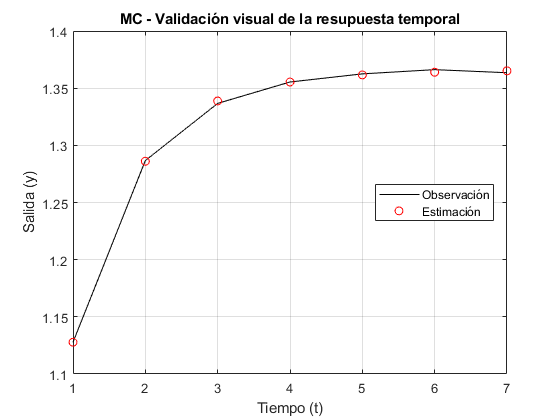

    % Validar
    t_plot = t(1+Q:end);
    plot(t_plot, Y, 'k', t_plot, y_est, 'or')
    grid on
    xlabel('Tiempo (t)'); ylabel('Salida (y)');
    legend({'Observación', 'Estimación'}, 'Location', 'best')
    title('MC - Validación visual de la resupuesta temporal')
    
else
    'Se requieren más datos.'
end

Al graficar la respuesta temporal a partir del modelo obtenido y la respuesta temporal experimental, se observa que los resultados han sido validados, pues la estimación se ajusta adecuadamente a la respuesta experimental observada.

function estimation = eq_arx(params, na, nb, nk)
% Entradas:
%   params: vector con de parámetros
%   na, nb, d: parámetros del ARX(na, nb, nk=d+1)
% Salida:
%   estimation: string con el modelo resultante
    estimation = 'y(t)';
    for i = 1:na
        estimation = [estimation, ' + ', num2str(params(i)), '*y(t-', num2str(i),')'];
    end
    estimation = [estimation, ' = '];
    for i = 1:nb
       estimation = [estimation, ' + ', num2str(params(i+na)), '*u(t-',num2str(nk),'-',...
                     num2str(i),')'];
    end
    estimation = replace(replace(estimation, '+ -', '- '), '=  +', '=');
end